global units
units = 'km';

%Configuracao Arquivo batimetria
batLon = [-45 -42];
batLat = [-24 -26];

rangeLon = max(batLon)-min(batLon);
rangeLonint = rangeLon*120;
rangeLat = max(batLat)-min(batLat);
rangeLatint = rangeLat*120;

M = dlmread("GEBCO2014_-45.0_-26.0_-42.0_-24.0_30Sec_ESRIASCII.asc", ' ', 6, 1);
latitude = linspace(batLat(1), batLat(2), rangeLatint);
longitude = linspace(batLon(1), batLon(2), rangeLonint);
latitudeKM = linspace(0, 222.4, rangeLatint);
KM_por_range = 222.4 / rangeLatint;

%Configuração do poço

% Conversões para Índice da Matriz
wellLonint = 120;
wellLatint = 120;

% Coloca a batimetria
wellBat = M(wellLonint, wellLatint);
wellLatLon = [-25 -43 wellBat];
wellInt = [wellLonint wellLatint wellBat];

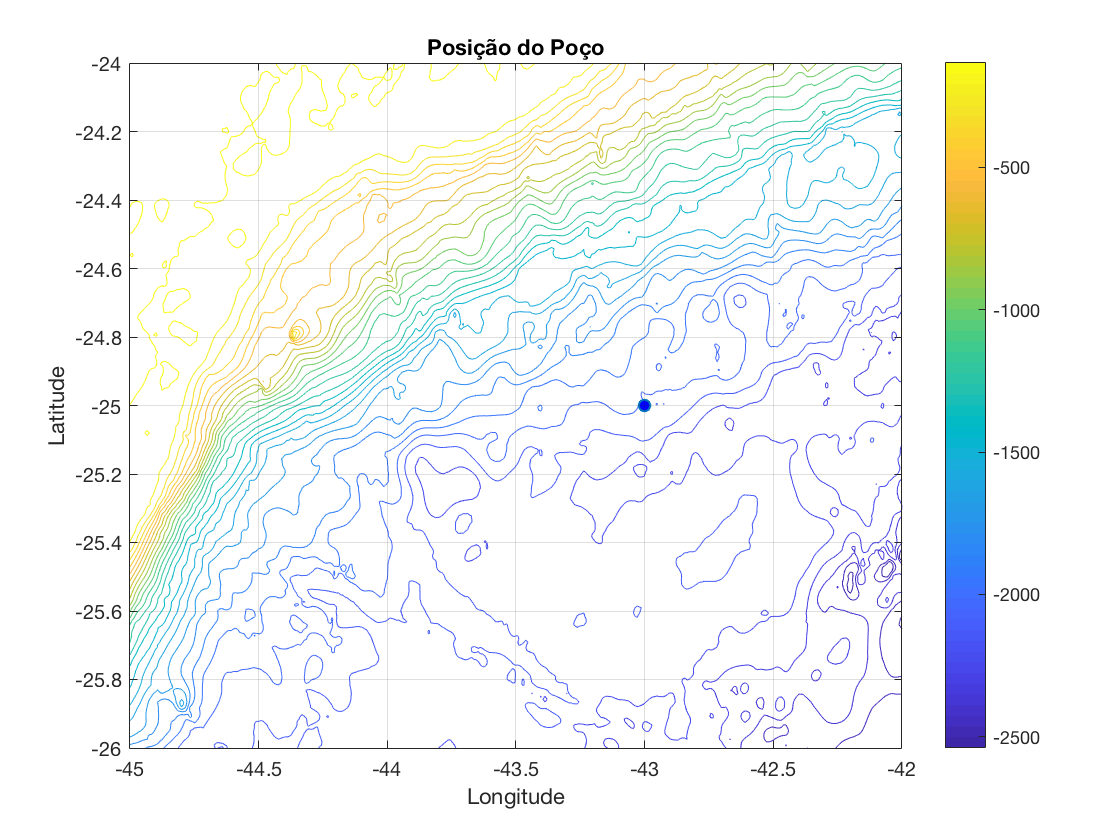

% Plot do contorno da região
figure
contour(longitude, latitude, M, 30)
hold on
plot(well(2),well(1),'o','MarkerFaceColor','b');
hold off
title('Posição do Poço')
xlabel('Longitude')
ylabel('Latitude')
grid on
colorbar

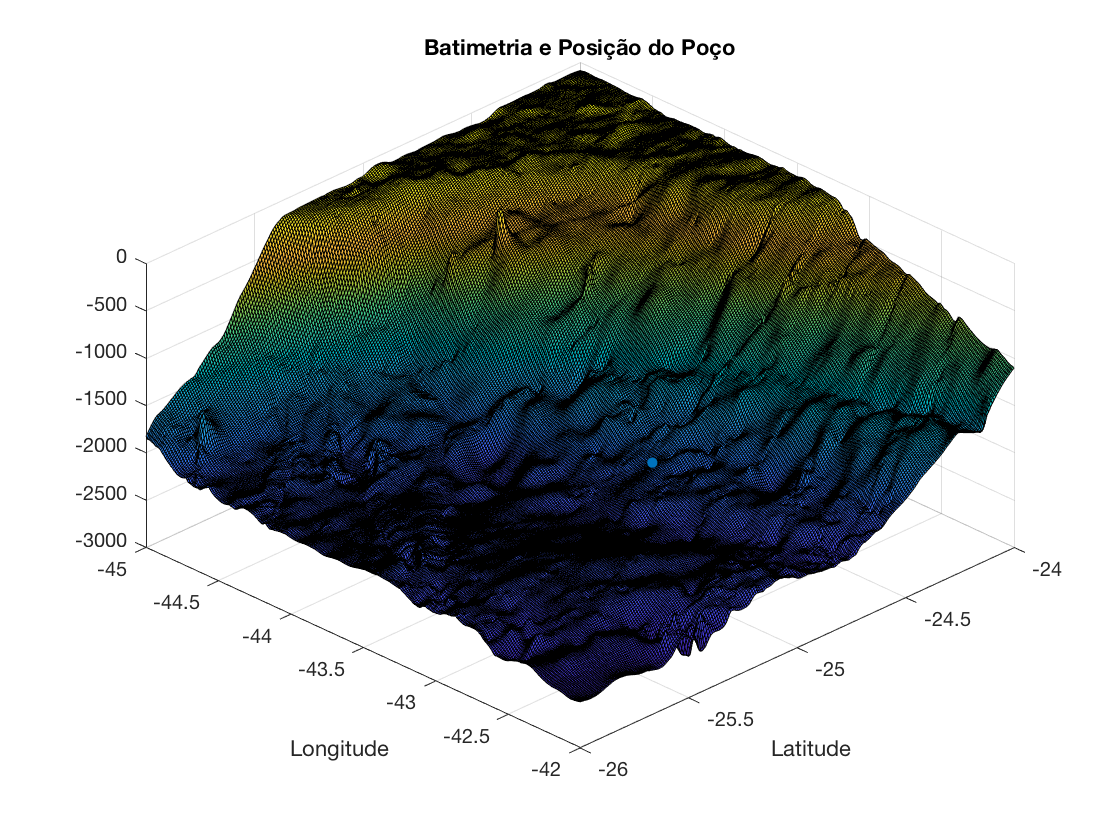

% Plot 3D da Região
figure
surf(longitude,latitude,M)
hold on
plot3(well(2),well(1),well(3),'.','MarkerSize',15)
hold off
view([45 45])
title('Batimetria e Posição do Poço')
xlabel('Longitude')
ylabel('Latitude')
grid on

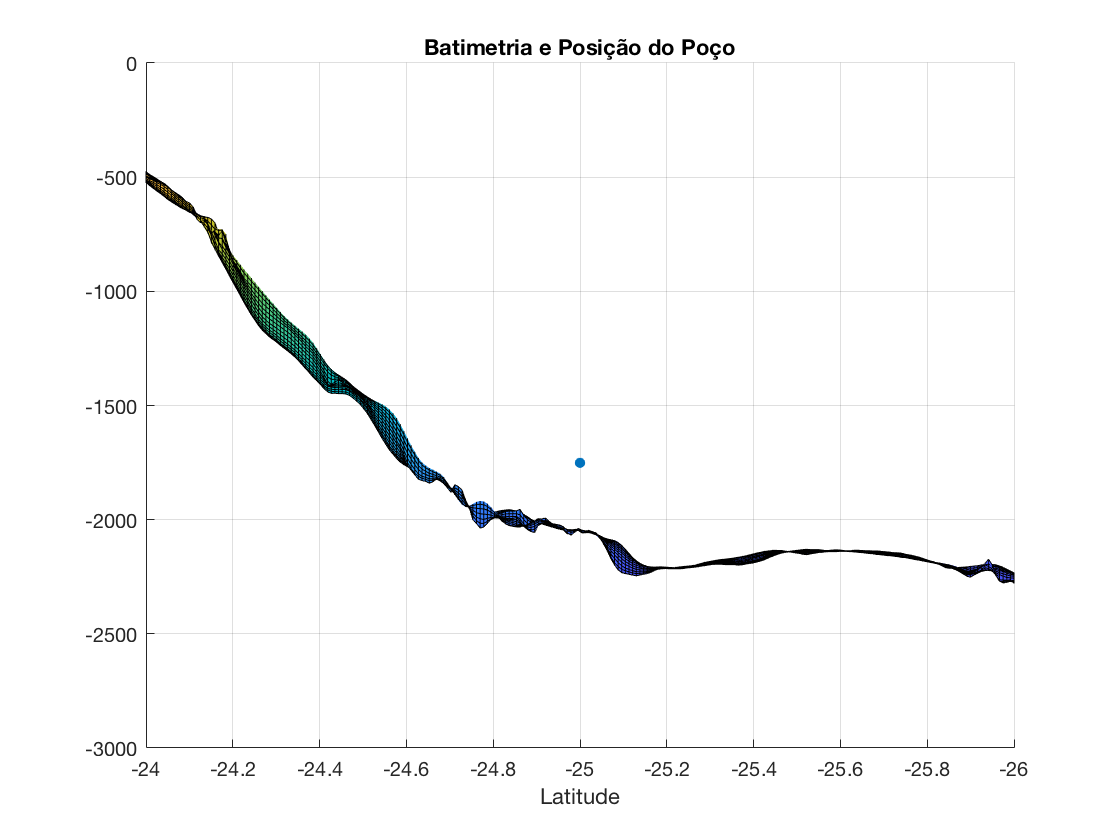

figure
surf(longitude,latitude,M)
hold on
plot3(well(2),well(1),well(3),'.','MarkerSize',15)
hold off
view([-90 0])
title('Batimetria e Posição do Poço')
xlabel('Longitude')
ylabel('Latitude')
grid on
xlim([-43 -42.9])
ylim([-26 -24])

% zlim([-2500 0])


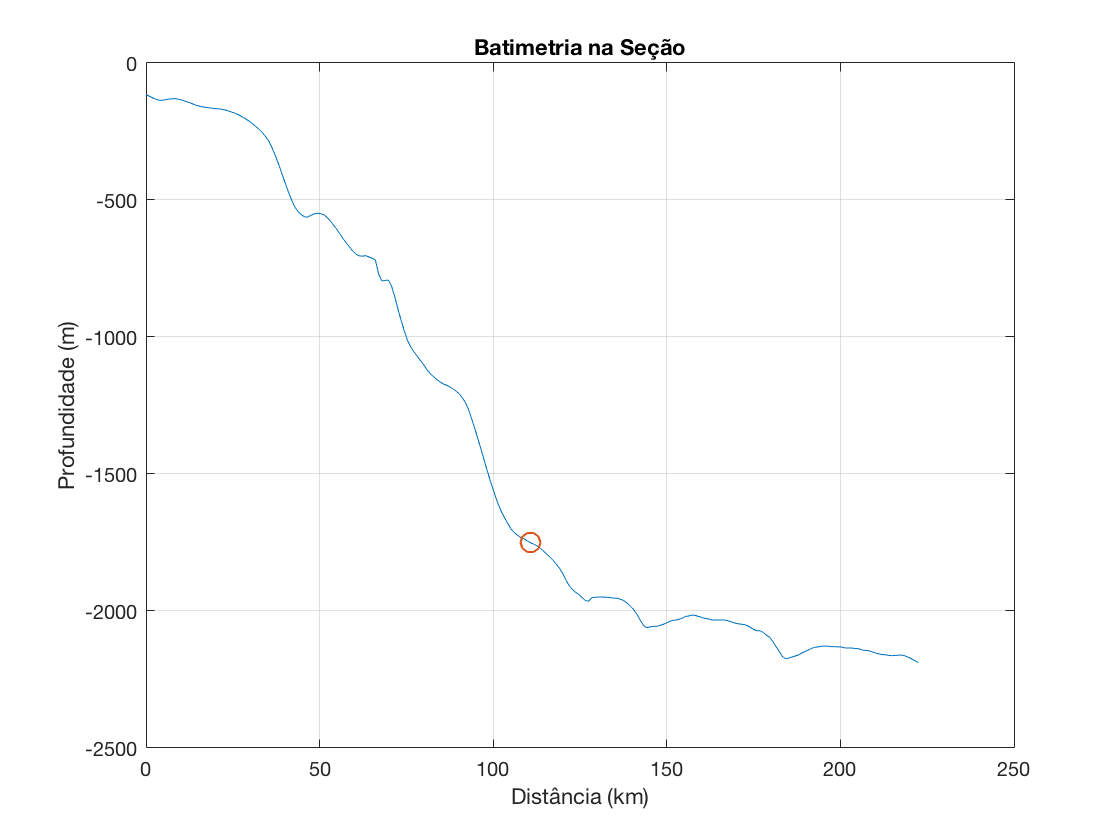

% Plot 2D da seção do poço
batimetria = M(:, wellLatint);
figure
plot(latitudeKM, batimetria)
title('Batimetria na Seção')
xlabel('Distância (km)')
ylabel('Profundidade (m)')
hold on
lat_poco = latitudeKM(wellInt(2));
plot(lat_poco,wellInt(3),'o','MarkerSize',10);
hold off
grid on

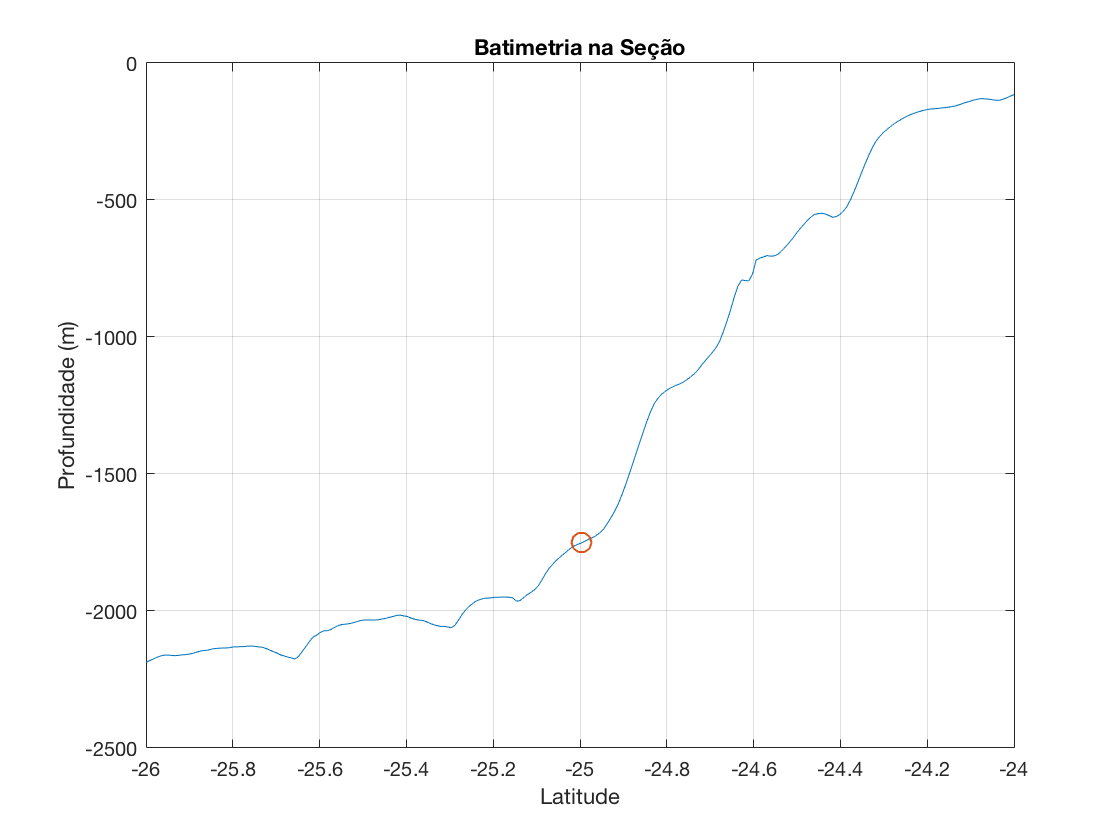

% Plot 2D da seção do poço
figure
plot(latitude, batimetria)
title('Batimetria na Seção')
xlabel('Latitude')
ylabel('Profundidade (m)')
hold on
lat_poco = latitude(wellInt(2));
plot(lat_poco,wellInt(3),'o','MarkerSize',10);
hold off
grid on

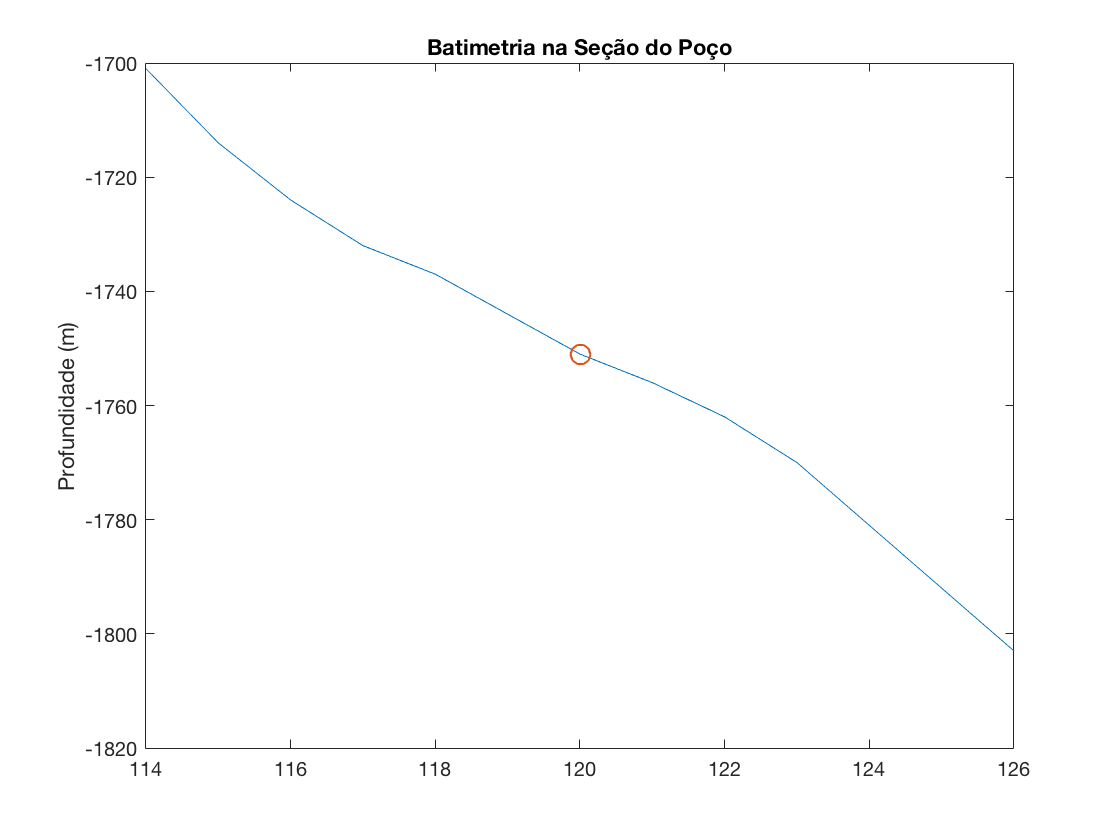

% Plot 2D da seção de batimetria a ser estudada
figure
plot(batimetria)
title('Batimetria na Seção do Poço')
ylabel('Profundidade (m)')
xlim([114 126])
hold on
plot(wellInt(2),wellInt(3),'o','MarkerSize',10);
hold off

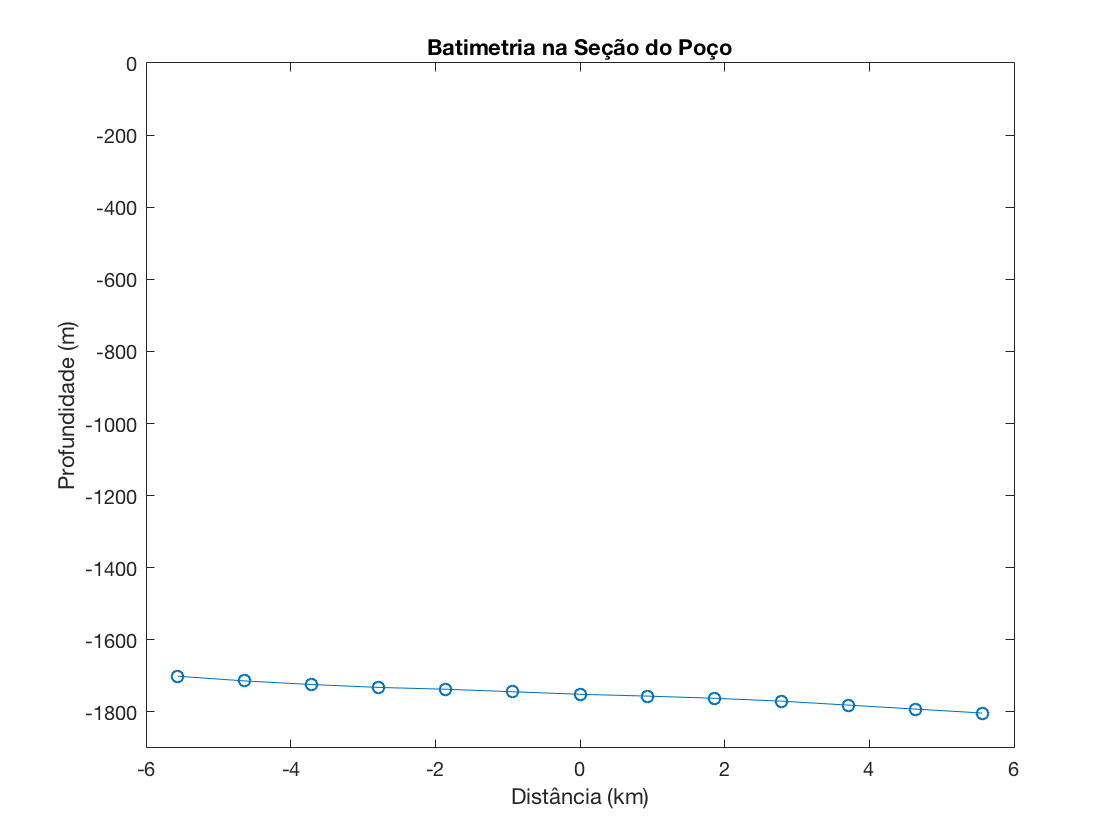

estudo = M(114:126, wellLonint);
xEstudado = linspace(-6*KM_por_range, 6*KM_por_range, 13);

figure
plot(xEstudado, estudo, '-o')
title('Batimetria na Seção do Poço')
xlabel('Distância (km)')
ylabel('Profundidade (m)')
ylim([-1900 0])

% Escreve arquivo de batimetria
fileID = fopen('MunkRay.bty','w');
TYPE = 'L';
formatSpec = '%s\r\n';
fprintf(fileID, formatSpec,TYPE);
COUNT = numel(estudo);
formatSpec = '%d\r\n';
fprintf(fileID, formatSpec, COUNT);
NPOINTS = [transpose(xEstudado) -estudo];
dlmwrite('MunkRay.bty',NPOINTS,'-append','delimiter',' ');

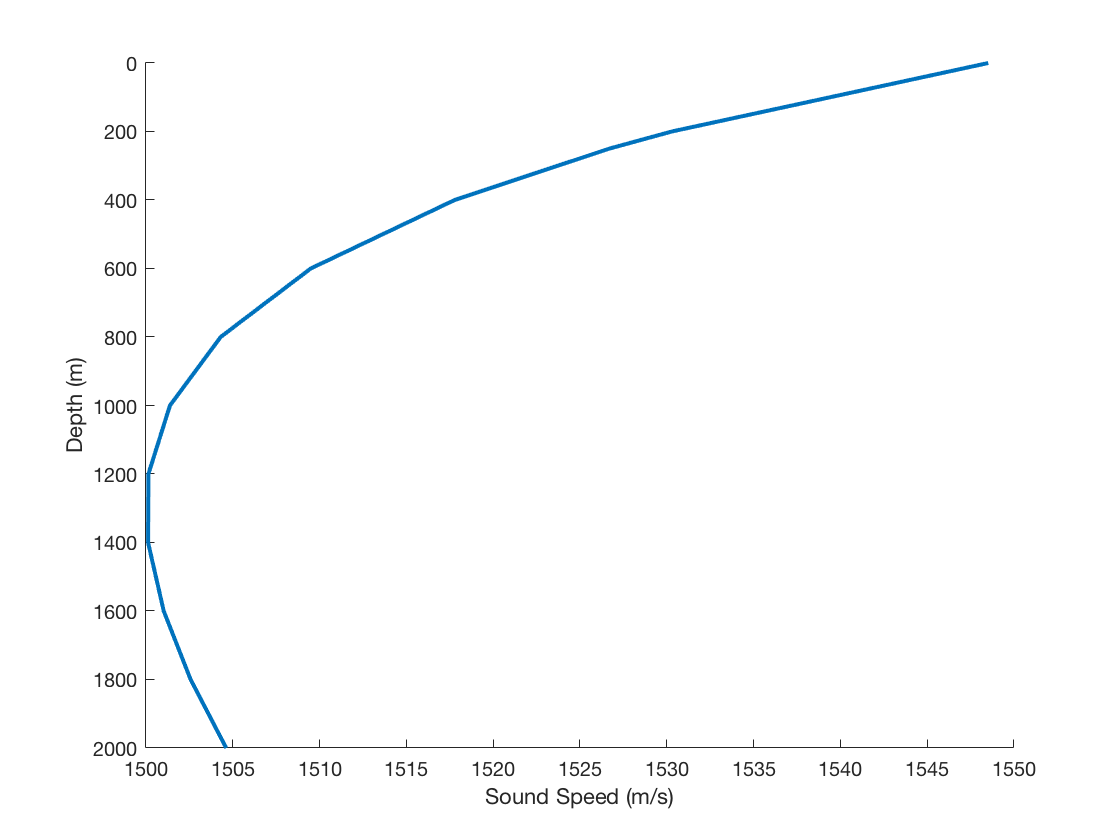

__________________________________________________________________
Santos Munk profile
Frequency = 50 Hz 
Number of media = 1 

    N2-Linear approximation to SSP
    Attenuation units: dB/wavelength
    VACUUM

   z (m)   alphaR (m/s)    betaR     rho (g/cm^3)  alphaI      betaI 
    ( Number of pts = 0  Roughness =   0.00  Depth =  2000.00 ) 
    0.00     1548.52        0.00        1.00      0.0000      0.0000 
  200.00     1530.29        0.00        1.00      0.0000      0.0000 
  250.00     1526.69        0.00        1.00      0.0000      0.0000 
  400.00     1517.78        0.00        1.00      0.0000      0.0000 
  600.00     1509.49        0.00        1.00      0.0000      0.0000 
  800.00     1504.30        0.00        1.00      0.0000      0.0000 
 1000.00     1501.38        0.00        1.00      0.0000      0.0000 
 1200.00     1500.14        0.00        1.00      0.0000      0.0000 
 1400.00     1500.12        0.00        1.00      0.0000      0.0000 
 1600.00     1501.02   

figure
plotssp('MunkRay');

bellhop('MunkRay');

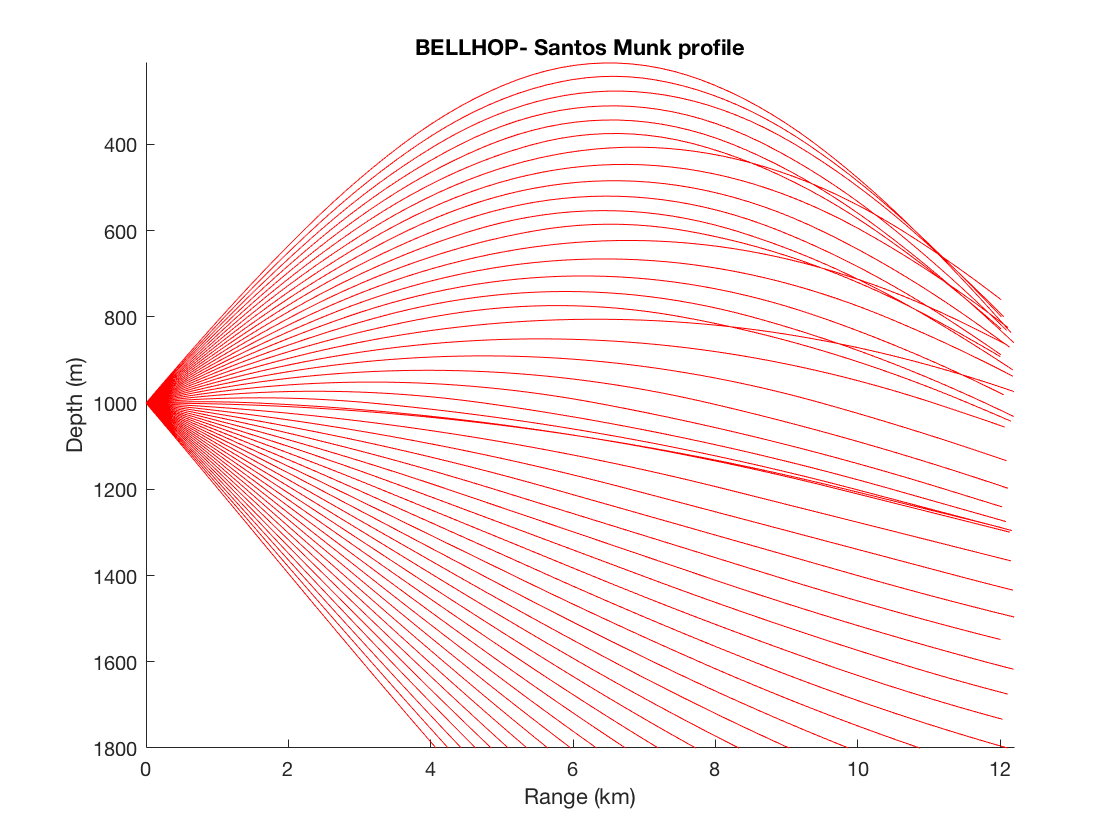

figure
plotray('MunkRay')


% plotbty('MunkTrabalho');